rng('default')

filename = "lessonlearned.csv";
data = readtable(filename,'TextType','String');
idx = strlength(data.event_narrative) == 0;
data(idx,:) = [];
idx2 = strlength(data.abstract) == 0;
data(idx2,:) = [];

textData = data.event_narrative;
textData(1:5)

ans = 5×1 string array
    "  Laboratory testing revealed higher than anticipated safety risks from a potential arc-flash event in a manhole environment when conducted at KSCês unreduced fault current levels.¾ The safety risks included bright flash, excessive sound, and smoke.¾¾ Due to these findings and absence of other mitigations installed at the time, manhole entries require full arc-flash PPE.¾ Furthermore, manhole entries were temporarily restricted to short duration inspections until further mitigations could be implemented.¾ With installation of neutral grounding resistors (NGRs) on substation transformers, the flash, sound and flame energy was reduced.¾ The hazard reduction was so substantial that the required PPE would be less cumbersome and enable effective performance of maintenance tasks in the energized configuration.¾  ↵  With the NGR installed, the surge arresters currently used at KSC are not designed for the load and may fail during a fault causing secondary outages a

textData2 = data.abstract;
textData2(1:5)

ans = 5×1 string array
    "  Power system distribution at Kennedy Space Center (KSC) consists primarily of high-voltage, underground cables. These cables include approximately 5000 splices.¾ Splice failures result in arc flash events that are extremely hazardous to personnel in the vicinity of the arc flash. Some construction and maintenance tasks cannot be performed effectively in the required personal protective equipment (PPE), and de-energizing the cables is not feasible due to cost, lost productivity, and safety risk to others implementing the required outages. To verify alternate and effective mitigations, arc flash testing was conducted in a controlled environment. The arc flash effects were greater than expected. Testing also demonstrated the addition of neutral grounding resistors (NGRs) would result in substantial reductions to arc flash effects. As a result, NGRs are being installed on KSC primary substation transformers. The presence of the NGRs, enable usage of less cumbe

documents = preprocessLessonLearned(textData);
documents(1:5)

ans =   5×1 tokenizedDocument:

    113 tokens: laboratory testing reveal high anticipate safety risk potential arcflash event manhole environment conduct kscês unreduced fault current level safety risk include bright flash excessive sound smoke due finding absence mitigation install time manhole entry require full arcflash ppe furthermore manhole entry temporarily restrict short duration inspection further mitigation implement installation neutral ground resistor ngrs substation transformer flash sound flame energy reduce hazard reduction substantial require ppe less cumbersome enable effective performance maintenance task energize configuration ngr install surge arrester currently ksc design load fail fault cause secondary outage increase repair time replacement surge arrester conduct year due result hundred facility outage impact surge suppressor upgraded ngrs manhole construction maintenance operation approve

documents2 = preprocessLessonLearned(textData2);
documents2(1:5)

ans =   5×1 tokenizedDocument:

    95 tokens: power system distribution kennedy space center ksc consist primarily highvoltage underground cable cable include approximately 5000 splice splice failure result arc flash event extremely hazardous personnel vicinity arc flash construction maintenance task perform effectively require personal protective equipment ppe deenergizing cable feasible due cost lost productivity safety risk others implementing require outage verify alternate effective mitigation arc flash testing conducted control environment arc flash effect great expect testing demonstrate addition neutral ground resistor ngrs result substantial reduction arc flash effect result ngrs install ksc primary substation transformer presence ngrs enable usage less cumbersome ppe increase
    33 tokens: sample analysis process verify cleanliness gas liquid load payload related ground support equipment gse introduce

bag = bagOfNgrams(documents)

bag =   bagOfNgrams with properties:

          Counts: [868×37987 double]
      Vocabulary: [1×6216 string]
          Ngrams: [37987×2 string]
    NgramLengths: 2
       NumNgrams: 37987
    NumDocuments: 868


bag2 = bagOfNgrams(documents2)

bag2 =   bagOfNgrams with properties:

          Counts: [868×29987 double]
      Vocabulary: [1×5558 string]
          Ngrams: [29987×2 string]
    NgramLengths: 2
       NumNgrams: 29987
    NumDocuments: 868


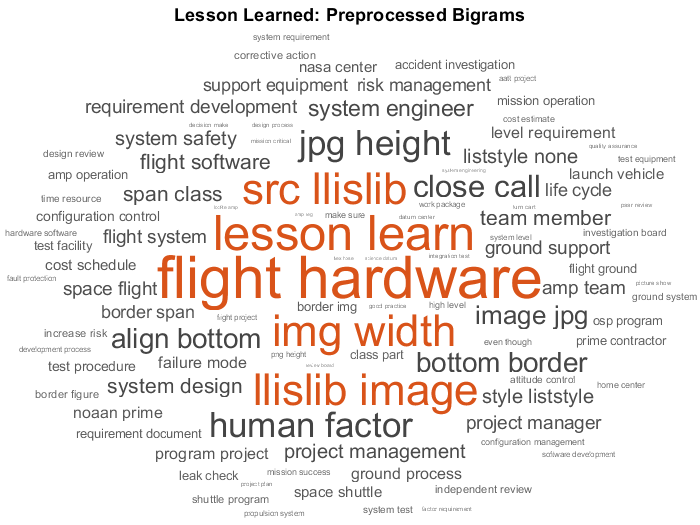

figure
wordcloud(bag);
title("Lesson Learned: Preprocessed Bigrams")

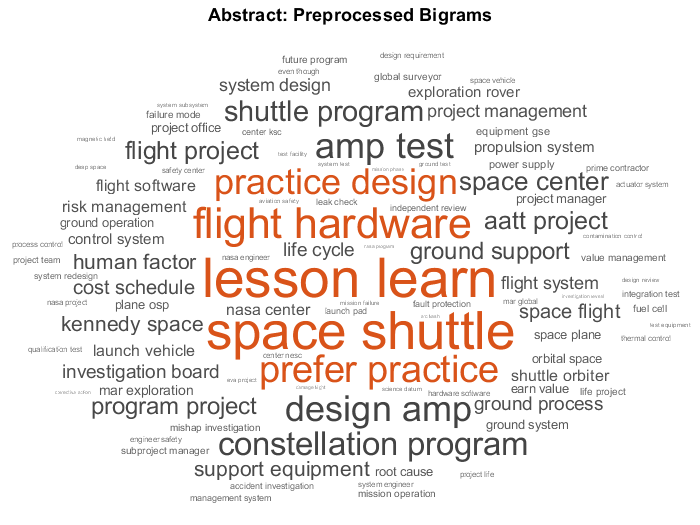

figure
wordcloud(bag2);
title("Abstract: Preprocessed Bigrams")

mdl = fitlda(bag,10);

Initial topic assignments sampled in 0.590179 seconds.
| Iteration  |  Time per  |  Relative  |  Training  |     Topic     |     Topic     |
|            | iteration  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |       0.22 |            |  2.930e+04 |         2.500 |             0 |
|          1 |       0.39 | 3.7247e-02 |  2.025e+04 |         2.500 |             0 |
|          2 |       0.37 | 7.0914e-04 |  2.011e+04 |         2.500 |             0 |
|          3 |       0.36 | 1.9147e-04 |  2.015e+04 |         2.500 |             0 |
|          4 |       0.37 | 2.0086e-03 |  1.975e+04 |         2.500 |             0 |
|          5 |       0.32 | 5.0473e-04 |  1.985e+04 |         2.500 |             0 |

mdl2 = fitlda(bag2,10);

Initial topic assignments sampled in 0.230227 seconds.
| Iteration  |  Time per  |  Relative  |  Training  |     Topic     |     Topic     |
|            | iteration  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |       0.10 |            |  2.242e+04 |         2.500 |             0 |
|          1 |       0.29 | 4.9393e-02 |  1.399e+04 |         2.500 |             0 |
|          2 |       0.24 | 1.5975e-03 |  1.378e+04 |         2.500 |             0 |
|          3 |       0.22 | 1.4038e-04 |  1.380e+04 |         2.500 |             0 |
|          4 |       0.25 | 1.2510e-05 |  1.380e+04 |         2.500 |             0 |

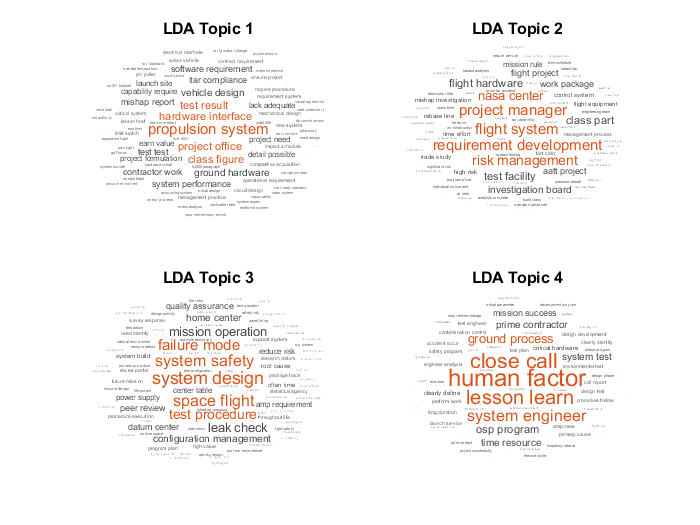

figure
for i = 1:4
    subplot(2,2,i)
    wordcloud(mdl,i);
    title("LDA Topic " + i)
end

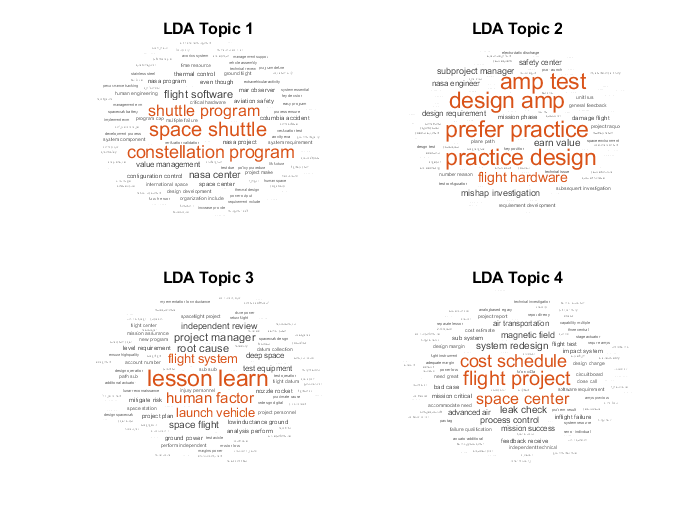

figure
for i = 1:4
    subplot(2,2,i)
    wordcloud(mdl2,i);
    title("LDA Topic " + i)
end

cleanTextData = erasePunctuation(textData);
documents = tokenizedDocument(cleanTextData);
cleanTextData2 = erasePunctuation(textData2);
documents2 = tokenizedDocument(cleanTextData2);

bag = bagOfNgrams(documents,'NGramLengths',3);
bag2 = bagOfNgrams(documents2,'NGramLengths',3);

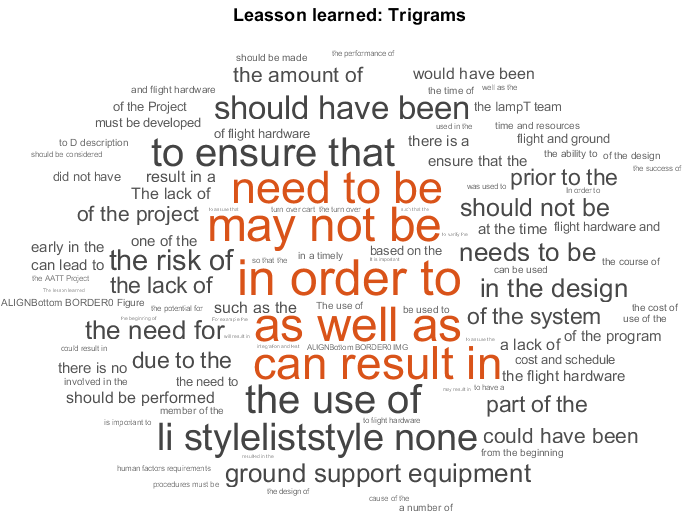

figure
wordcloud(bag);
title("Leasson learned: Trigrams")

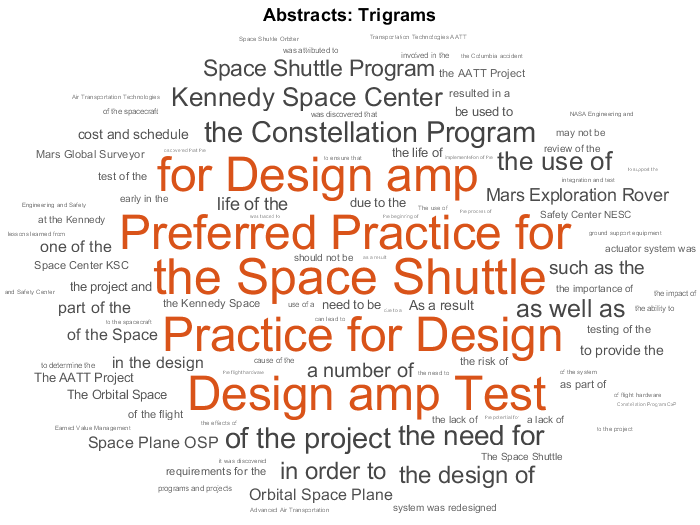

figure
wordcloud(bag2);
title("Abstracts: Trigrams")

tbl = topkngrams(bag,10)

tbl = 10×3 table
                    Ngram                     Count    NgramLength
    ______________________________________    _____    ___________

    "in"        "order"             "to"       33           3     
    "as"        "well"              "as"       31           3     
    "may"       "not"               "be"       31           3     
    "can"       "result"            "in"       30           3     
    "need"      "to"                "be"       29           3     
    "the"       "use"               "of"       26           3     
    "to"        "ensure"            "that"     26           3     
    "li"        "styleliststyle"    "none"     24           3     
    "should"    "have"              "been"     21           3     
    "the"       "risk"              "of"       19           3     


tbl2 = topkngrams(bag2,10)

tbl2 = 10×3 table
                       Ngram                       Count    NgramLength
    ___________________________________________    _____    ___________

    "the"          "Space"            "Shuttle"     51           3     
    "Preferred"    "Practice"         "for"         47           3     
    "Practice"     "for"              "Design"      47           3     
    "for"          "Design"           "amp"         47           3     
    "Design"       "amp"              "Test"        47           3     
    "the"          "Constellation"    "Program"     26           3     
    "of"           "the"              "project"     26           3     
    "the"          "need"             "for"         25           3     
    "Kennedy"      "Space"            "Center"      24           3     
    "the"          "use"              "of"          24           3     


function [documents] = preprocessLessonLearned(textData)


cleanTextData = lower(textData);


documents = tokenizedDocument(cleanTextData);


documents = erasePunctuation(documents);


documents = removeStopWords(documents);


documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);


documents = addPartOfSpeechDetails(documents);
documents = normalizeWords(documents,'Style','lemma');
end